# Hamiltonian Passivity Enforcement

## Introduction

Hamiltonian passivity enforcement is a method to enforce positive realness of a reduced order model [1]. An asymptotically stable system is positive real if the Hamiltonian matrix


$$N = \pmatrix{A-B(D+D^\mathrm{T})^{-1}C & -B (D+D^\mathrm{T})^{-1} B^\mathrm{T} \cr C^\mathrm{T} (D+D^\mathrm{T})^{-1} C & -A^\mathrm{T} +C^\mathrm{T} (D+D^\mathrm{T})^{-1} B^\mathrm{T}}$$


has no purely imaginary eigenvalues. If some are present the output matrix $C$ is perturbed to move them off the imaginary axis. To this end, two eigenvalues must collide and enforce a bifurcation process. To make the approach $\mathcal{H}_2$-optimal, a coordinate change is utilized. Since perturbation of the eigenvalues


$$\tilde{\lambda}_k \approx \lambda_k + \frac{w_k^\mathrm{H}Nv_k}{w_k^\mathrm{H}v_k}$$


is only approximate the approach is applied iteratively. To find the minimal perturbation $\xi$ that moves the Hamiltonian eigenvalue from $\lambda_k$ to $\hat{\lambda}_k$ we can set up a constraint quadratic program

$\min_\xi ||\xi||^2_2 \quad \text{s.t.} \quad z_k^\mathrm{T}\xi \ge \eta_k$, 

where the information about the constraint problem is stored in $z_k$ and $\eta_k$. To perturb multiple eigenvalues at once the problem is rewritten in compact form as

$\min_\xi ||\xi||^2_2 \quad \text{s.t.} \quad Z\xi \ge \eta$.

Here, $Z=(z_1,z_2,\ldots,z_K)^\mathrm{T}$ and $\eta = (\eta_1,\eta_2,\ldots,\eta_K)^\mathrm{T}$.

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of Hamiltonian passivity enforcement in the function *hamPasEnf*.

For more information, refer to the documentation:

help hamPasEnf

  hamPasEnf - Enforce passivity of sys by applying Hamiltonian passivity
              constraints.
 
  Syntax:
    sysp = hamPasEnf(sys)
    sysp = hamPasEnf(sys,opts)
 
  Description:
        sysp = hamPasEnf(sys,opts)
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:      sss-object, containing LTI system
        *Optional Input Arguments:*
        - Opts:  structure with execution parameters
            - .step:            Factor controlling how much matrix C is perturbed.
                                [{1} / double]
            - .verbose:         Control console output.
                                [{0} / 1]
            - .maxIter:         Maximum number of iterations.
                                [{1000} / positive integer]
            - .alpha:           Control parameter for computation of new locations.
                                [{0.5} / double]
            - .makePH:      

## Example

The example considered here is a randomly generated non passive system.

rng('default')
sys = setup_RandomSystem(10,1,-1e-3)

sys =   (DSSS)(SISO)
  10 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


We take a look at its bode plot:

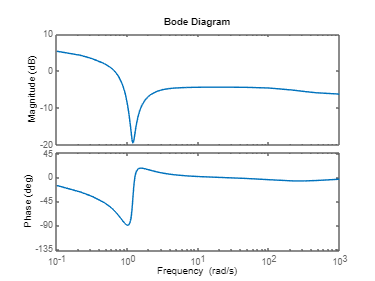

bode(sys)

*hamPasEnf* in its simplest form is called by providing the non-passive system: 

warning('off','all')
sysr = hamPasEnf(sys)

	 Algorithm converged.

sysr =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10
   x1   -31.85   -18.1  -38.95  -23.82  -39.71  -54.34  -34.16  -48.09       0       0
   x2    29.05   16.09   35.01   20.67   36.11   49.67   31.42   44.48       0       0
   x3    -32.1  -18.26  -40.43  -24.39   -41.9  -57.24  -37.82  -51.59       0       0
   x4   -10.09  -4.983  -11.92  -8.418  -12.14   -17.7  -11.16  -15.02       0       0
   x5   -42.45  -25.34  -53.82  -33.01  -56.37  -76.31  -50.78  -68.87       0       0
   x6   -32.97  -18.69   -40.4  -25.07  -41.88  -58.56  -37.87  -51.77       0       0
   x7    13.02   7.341   15.47   9.667   15.06   22.23   12.13   18.54       0       0
   x8   -47.97  -28.27  -59.28  -35.87  -61.87  -84.64  -55.06  -76.53       0       0
   x9        0       0       0       0       0       0       0       0       0       1
   x10       0       0       0       0       0       0       0       0      -1      -1
 
 

norm(ss(sys) - ss(sysr))

ans = 4.4930e-04

isPassive(ss(sysr))

ans = logical
   1


### Options

*hamPasEnf* provides different (nested) options. The levels of options are:

- Top level (*hamPasEnf*): e.g. step length

- Second level (shamPassive): e.g. tolerance for purely imaginary eigenvalues

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help ss2phs

  ss2phs - Returns pH system representation of a given passive system
 
  Syntax:
    sysPH = ss2phs(sys)
    sysPH = ss2phs(sys,X)
    sysPH = ss2phs(sys,Opts)
    sysPH = ss2phs(sys,X,Opts)
 
  Description:
        This funciton uses the Kalman-Yakubovic-Popov Lemma to construct a
        port-Hamiltonian system representation of a given passive
        ss object.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  ss object to be brought in pH representation
        *Optional Input Arguments:*
        - X: solution to positive real Riccati equation
        - Opts: structure with execution parameters
            - .tol:             If D+D' is not positive definite, D is replaced
                                by Opts.tol*eye(m).
                                [{1e-12} / positive double]
            - .representation:  Defines the pH system representation
                       

To provide these options, use nested structs. As example, the following code changes the reduced system to be port-Hamiltonian:

Opts = struct();
Opts.makePH = true;     % Return pH system
Opts.ss2phs.method = @hamPasEnf; % Reduction method for info
Opts

Opts = struct with fields:
    makePH: 1
    ss2phs: [1×1 struct]


sysr = hamPasEnf(sys,Opts)

	 Algorithm converged.


sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @hamPasEnf
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0.4764
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


norm(ss(sys) - ss(sysr))

ans = 4.4930e-04

### Output

*hamPasEnf* provides only the passive system as output. This ssRed/phsRed object contains additional information which makes the creation more transparent:

sysr.method    % Method with which the system was created (should be @hamPasEnf)

ans = function_handle with value:
    @hamPasEnf


sysr.parameters     % Execution parameters (options)         

ans = struct with fields:
         makePH: 1
         ss2phs: [1×1 struct]
    shamPassive: [1×1 struct]
           step: 1
        verbose: 0
        maxIter: 1000
          alpha: 0.5000
       quadprog: [1×1 optim.options.Quadprog]


## References

[1] Grivet-Talocia, Gustavsen, "Passive Macromodeling Theory and Applications", 2016.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)